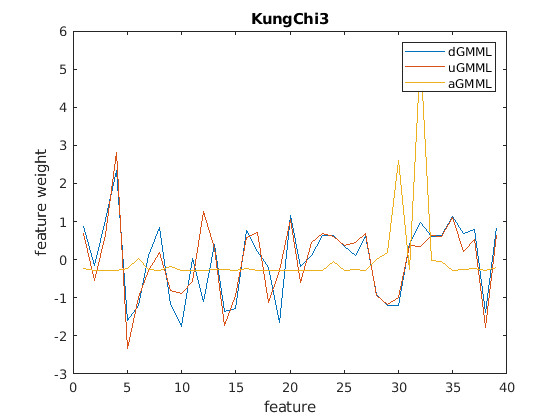

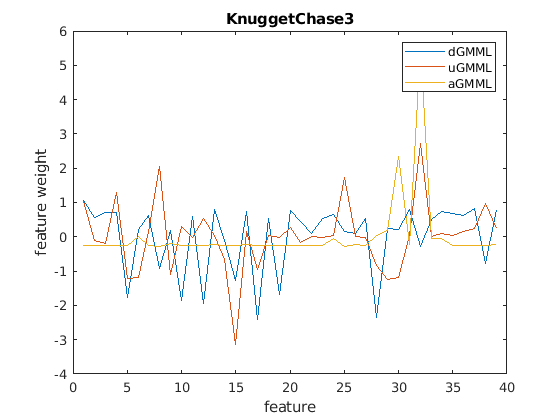

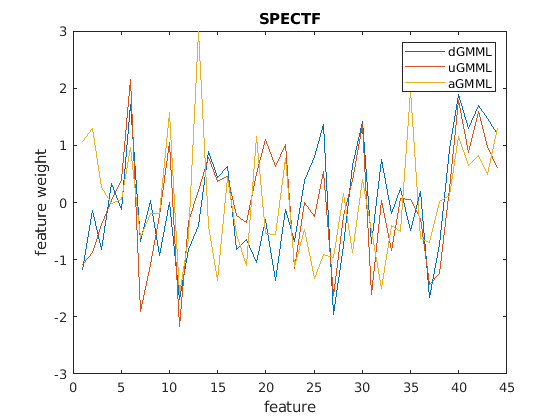

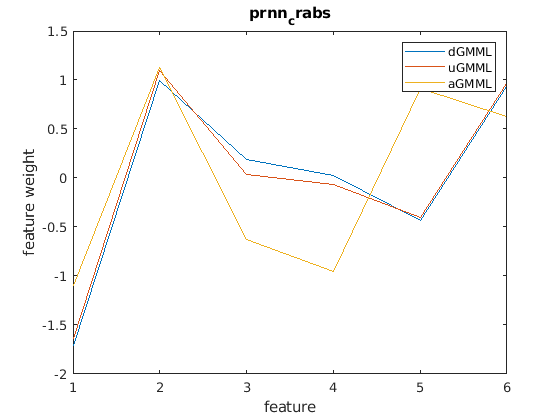

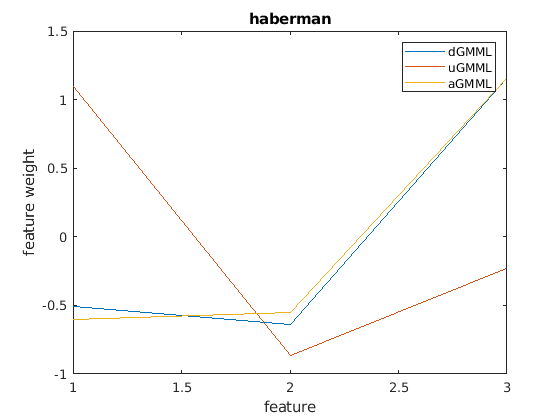

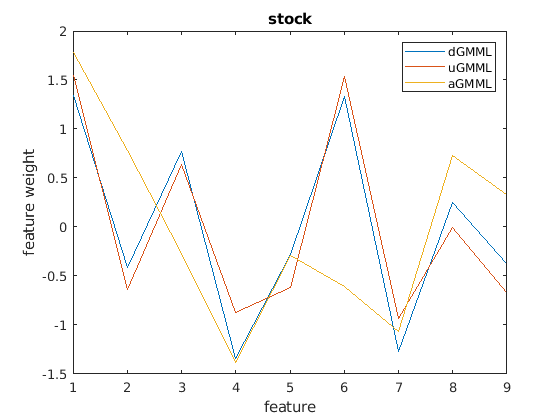

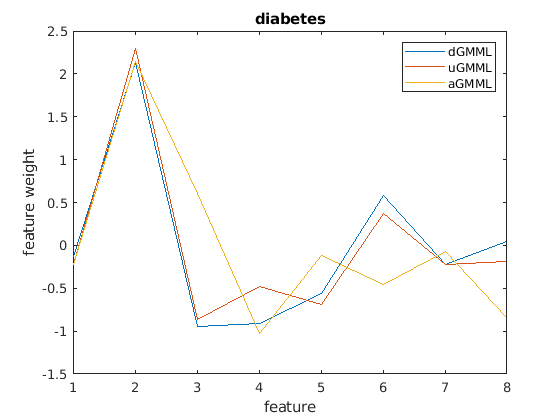

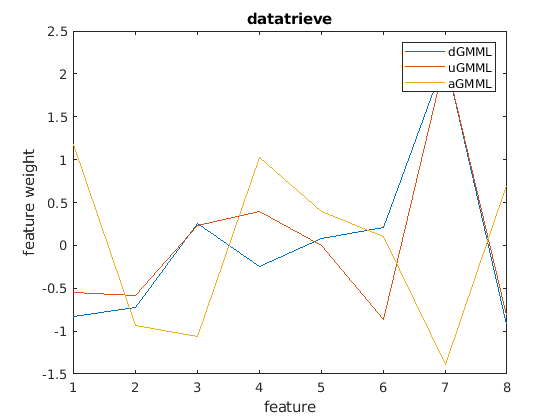

for idx = 1:1:47       
    clearvars -except idx seed ret_RF ret_my 
    dataset = {'KungChi3','KnuggetChase3','SPECTF','prnn_crabs','haberman','stock','diabetes','datatrieve','banknote-authentication','ilpd','sonar','spambase','heart-statlog','monks-problems-1','monks-problems-2','monks-problems-3','mfeat-morphological','ionosphere','blood-transfusion-service-center','balloons','breast-cancer-wisc-diag_R','breast-cancer-wisc-prog_R','conn-bench-sonar-mines-rocks_R','cylinder-bands_R','dermatology_R','echocardiogram_R','fertility_R','haberman-survival_R','heart-hungarian_R','hepatitis_R','ilpd-indian-liver_R','ionosphere_R','lymphography_R','mammographic_R','molec-biol-promoter_R','oocytes_merluccius_nucleus_4d_R','oocytes_trisopterus_nucleus_2f_R','oocytes_trisopterus_states_5b_R','parkinsons_R','pima_R','pittsburg-bridges-T-OR-D_R','planning_R','post-operative_R','statlog-australian-credit_R','statlog-german-credit_R','statlog-heart_R','vertebral-column-2clases_R'};%'gina_prior','MiniBooNE'
    if idx<=19
      [train_examples,train_labels,test_examples,test_labels] = getdata(dataset{idx},5,1);
    else
       [train_examples,train_labels,test_examples,test_labels] = getdataUCI(dataset{idx},5,1);
    % train a Decision Tree classifier from the training data:
    end
     label = unique(train_labels);
     k = size(label,1);
     X1 = train_examples(find(train_labels==label(1)),:);
     X1 = table2array(X1);
     X2 = train_examples(find(train_labels==label(2)),:);
     X2 = table2array(X2);
     x1=size(X1,1);
     x2=size(X2,1);
     m1 = mean(X1,1);
     m2 = mean(X2,1);
     m = size(X1,2);
            
     mix1_shuffled = X1(randperm(x1), :);
     mix2_shuffled = X2(randperm(x2), :);
     minx = min(x1,x2);
     mix1_shuffled = mix1_shuffled(1:minx,:);            
     mix2_shuffled = mix2_shuffled(1:minx,:);
     mix = (mix1_shuffled + mix2_shuffled)/2;
     mixm = mean(mix,1);
            
     m1_mat = repmat(m1,x1,1);
     m2_mat = repmat(m2,x2,1);
     mix_mat = repmat(mixm,minx,1);
     x1_m1 = (X1-m1_mat).^2;
     x2_m2 = (X2-m2_mat).^2;
     xu_m = (mix - mix_mat).^2;
     m1_m2 = (m1-m2).^2;
     sum1 = sum(x1_m1,1)/x1;
     sum2 = sum(x2_m2,1)/x2;
     sum3 = sum(xu_m, 1)/minx;
     lamda = 5;
     denominator = sum1 + sum2;
     k = find(denominator == 0);
     denominator(1,k) = 1;
     m1_m2(1,k) = m1_m2(1,k) + 1;
     w1 = (m1_m2) ./ (denominator);
     wu = (m1_m2 + lamda*sum3) ./ (denominator + lamda*sum3);
     
     AA = MetricLearning(train_examples,train_labels);
     wa = diag(AA);
     w1 = zscore(w1.^(1/2));
     wu = zscore(wu.^(1/2));
     wa = zscore(wa);
     x = 1:size(w1,2);
     figure;
     plot(x,w1)    
     hold on;
     plot(x,wu);
     hold on;
     plot(x,wa);
     hold on;
     xlabel('feature');
     ylabel('feature weight');
     legend('dGMML','uGMML','aGMML')
     title(dataset(idx));         
     hold off;
 end